clear;
close all;
bdclose('all');

## Environment Setup

Ts = 0.1;           % simulation time step in sec
Ts_data = 0.5;      % time step to collect data in sec
T = 30;             % simulation time
D_default = 10;     % default distance
v_set = 30;         % driver-set velocity for ego car
t_gap = 1.4;        % time gap to calculate safe distance
vmin_lead = 2;      % lead car minimum velocity
      
vmax_ego = 50;      % ego car minimum/maximum velocity
vmin_ego = -50;

amin_ego = -3;      % ego car minimum/maximum acceleration
amax_ego = 2;       

x0_lead = 70;       % lead car initial velocity and position
v0_lead = 30;
a_lead_seed = 0;    % seed to generate random input a_lead

x0_ego = 10;        % ego car initial velocity and position
v0_ego = 25;

amin_lead = -1;     % lead car minimum/maximum acceleration
amax_lead = 1;

rewardDim = 2;       % reward dimension [distanceReward, velocityReward]

% input to simulink: take a_lead from a uniform distribution
change_freq = 2;    % input signal change value every change_freq sec

## DRL Obs/Act configuration

Creating an environment model includes action, obervation

**Observation**: 

- Target velocity: v_set or v_lead

- Ego car velocity

- Relative distance

- Relative velocity

- Safety distance

**Action**: Ego car acceleration

% observation
obsInfo = rlNumericSpec([5 1],...
    'LowerLimit', -inf*ones(5,1),...
    'UpperLimit', inf*ones(5,1));
obIsnfo.Name = 'observation';
obsInfo.Description = 'v_target, v_rel, v_ego, d_safe, d_rel';
numObservations = obsInfo.Dimension(1);

% action
actInfo = rlNumericSpec([1 1]);
actInfo.LowerLimit = amin_ego;
actInfo.UpperLimit = amax_ego;
actInfo.Name = 'action';
numActions = actInfo.Dimension(1);

mdl = 'ACC_RL_train';
agentblk = [mdl, '/RL Agent'];

% Build the environment interface object.
env = rlSimulinkEnv(mdl,agentblk,obsInfo,actInfo);

% Set a custom reset function that randomizes the reference values for the model.
% env.ResetFcn = @(in)localResetFcn(in);

% Fix the random generator seed for reproducibility
% rng(0);

## DRL Agent Configuration

[https://www.mathworks.com/help/reinforcement-learning/ref/rlddpgagent.html](https://www.mathworks.com/help/reinforcement-learning/ref/rlddpgagent.html)

**Create a network to be used as underlying critic approximator**

[https://www.mathworks.com/help/reinforcement-learning/ref/rlqvaluefunction.html#mw_7ca25508-5448-42fe-bb4e-61d437328c47](https://www.mathworks.com/help/reinforcement-learning/ref/rlqvaluefunction.html#mw_7ca25508-5448-42fe-bb4e-61d437328c47)

statePath = [
    featureInputLayer(numObservations,'Normalization','none','Name','observation')
    fullyConnectedLayer(32,'Name','CriticStateFC1')
    reluLayer('Name','CriticRelu1')
    fullyConnectedLayer(64,'Name','CriticStateFC2')];

actionPath = [
    featureInputLayer(1,'Normalization','none','Name','action')
    fullyConnectedLayer(32,'Name','CriticActionFC1')
    reluLayer('Name','ActorRelu1')
    fullyConnectedLayer(64,'Name','CriticActionFC2')];

commonPath = [
    additionLayer(2,'Name','add')
    reluLayer('Name','CriticCommonRelu1')
    fullyConnectedLayer(128,'Name','CriticCommonFC1')
    reluLayer('Name','CriticCommonRelu2')
    fullyConnectedLayer(64,'Name','CriticCommonFC2')
    reluLayer('Name','CriticCommonRelu3')
    fullyConnectedLayer(21,'Name','CriticCommonFC3')
    reluLayer('Name','CriticCommonRelu4')
    fullyConnectedLayer(1,'Name','CriticOutput')];

criticNetwork = layerGraph(statePath);
criticNetwork = addLayers(criticNetwork,actionPath);
criticNetwork = addLayers(criticNetwork,commonPath);
criticNetwork = connectLayers(criticNetwork,'CriticStateFC2','add/in1');
criticNetwork = connectLayers(criticNetwork,'CriticActionFC2','add/in2');

% convert the network to a dlnetwork object
criticNetwork = dlnetwork(criticNetwork);
% create 1st critics based on the network approximator
critic1 = rlQValueFunction(criticNetwork,obsInfo,actInfo,'UseDevice','cpu');

Second Critic with different NN structure

statePath = [
    featureInputLayer(numObservations,'Normalization','none','Name','observation')
    fullyConnectedLayer(64,'Name','CriticStateFC1')
    reluLayer('Name','CriticRelu1')
    fullyConnectedLayer(128,'Name','CriticStateFC2')];

actionPath = [
    featureInputLayer(1,'Normalization','none','Name','action')
    fullyConnectedLayer(64,'Name','CriticActionFC1')
    reluLayer('Name','ActorRelu1')
    fullyConnectedLayer(128,'Name','CriticActionFC2')];

commonPath = [
    additionLayer(2,'Name','add')
    reluLayer('Name','CriticCommonRelu1')
    fullyConnectedLayer(256,'Name','CriticCommonFC1')
    reluLayer('Name','CriticCommonRelu2')
    fullyConnectedLayer(128,'Name','CriticCommonFC2')
    reluLayer('Name','CriticCommonRelu3')
    fullyConnectedLayer(64,'Name','CriticCommonFC3')
    reluLayer('Name','CriticCommonRelu4')
    fullyConnectedLayer(1,'Name','CriticOutput')];

criticNetwork = layerGraph(statePath);
criticNetwork = addLayers(criticNetwork,actionPath);
criticNetwork = addLayers(criticNetwork,commonPath);
criticNetwork = connectLayers(criticNetwork,'CriticStateFC2','add/in1');
criticNetwork = connectLayers(criticNetwork,'CriticActionFC2','add/in2');

% convert the network to a dlnetwork object
criticNetwork = dlnetwork(criticNetwork);

% create 2nd critics based on the network approximator
critic2 = rlQValueFunction(criticNetwork,obsInfo,actInfo,'UseDevice','cpu');

**Create a network to be used as underlying actor approximator**

[https://www.mathworks.com/help/reinforcement-learning/ref/rlsacagent.html#mw_21dad7ed-6c6f-40b4-af0c-57ff290fee6e](https://www.mathworks.com/help/reinforcement-learning/ref/rlsacagent.html#mw_21dad7ed-6c6f-40b4-af0c-57ff290fee6e)

statePath = [
    featureInputLayer(prod(obsInfo.Dimension), ...
        'Normalization','none','Name','observation')
    fullyConnectedLayer(400, 'Name','commonFC1')
    reluLayer('Name','CommonRelu')];

meanPath = [
    fullyConnectedLayer(300,'Name','MeanFC1')
    reluLayer('Name','MeanRelu')
    fullyConnectedLayer(prod(actInfo.Dimension),'Name','Mean')
    ];

stdPath = [
    fullyConnectedLayer(300,'Name','StdFC1')
    reluLayer('Name','StdRelu')
    fullyConnectedLayer(prod(actInfo.Dimension),'Name','StdFC2')
    softplusLayer('Name','StandardDeviation')];

actorNetwork = layerGraph(statePath);
actorNetwork = addLayers(actorNetwork,meanPath);
actorNetwork = addLayers(actorNetwork,stdPath);

actorNetwork = connectLayers(actorNetwork,'CommonRelu','MeanFC1/in');
actorNetwork = connectLayers(actorNetwork,'CommonRelu','StdFC1/in');

actor = rlContinuousGaussianActor(actorNetwork, obsInfo, actInfo, ...
    'ActionMeanOutputNames','Mean',...
    'ActionStandardDeviationOutputNames','StandardDeviation',...
    'ObservationInputNames','observation');

**DRL agent options**

[https://www.mathworks.com/help/reinforcement-learning/ref/rlddpgagentoptions.html](https://www.mathworks.com/help/reinforcement-learning/ref/rlddpgagentoptions.html)

**Noise model:**

- It is common to set `StandardDeviation*sqrt(Ts)` to a value between 1% and 10% of your action rang. **[0.158, 1.58]**

- To increase exploration, you can reduce the `StandardDeviationDecayRate`.

% Optimization options for actors and critics
myCriticOpts=rlOptimizerOptions(...
    'LearnRate',1e-4,...
    'GradientThreshold',1,...
    'GradientThresholdMethod',"l2norm",...
    'L2RegularizationFactor', 1e-4,...
    'Optimizer',"adam");

myActorOpts=rlOptimizerOptions(...
    'LearnRate',1e-4,...
    'GradientThreshold',1,...
    'GradientThresholdMethod',"l2norm",...
    'L2RegularizationFactor', 1e-4,...
    'Optimizer',"adam");

% Options for SAC agent
agentOptions = rlSACAgentOptions(...
    'CriticOptimizerOptions', myCriticOpts,...
    'ActorOptimizerOptions',myActorOpts,...
    'SampleTime',Ts,...
    'TargetSmoothFactor',1e-3,...
    'TargetUpdateFrequency',1,...
    'ExperienceBufferLength',1e4,...
    'NumStepsToLookAhead',20,...
    'MiniBatchSize',128,...
    'DiscountFactor',0.99);

initOpts = rlAgentInitializationOptions('NumHiddenUnit',256);

% agent creation
% agent = rlSACAgent(obsInfo,actInfo,initOpts,agentOptions);
agent = rlSACAgent(actor,[critic1 critic2],agentOptions);

## **Training Configurations**

Change the weights distribution among subsitutional rewards

maxepisodes = 5000; 
maxsteps = ceil(T/Ts);
windowLength = 20;

% change reward weights distribution
rewardWeights = [0.3, 0.7, 0.1];

trainOpts = rlTrainingOptions(...
    'MaxEpisodes', maxepisodes, ...
    'MaxStepsPerEpisode', maxsteps, ...
    'ScoreAveragingWindowLength',windowLength, ...
    'StopTrainingCriteria','AverageReward',...
    'StopTrainingValue', 1*maxsteps*0.95,...
    'SaveAgentCriteria','AverageReward',...
    'SaveAgentValue', 1*maxsteps*0.9,...
    'Verbose', false,...
    'Plots','training-progress',...
    'UseParallel',false);

doTraining = true;

if doTraining
    % Train the agent.
    isTerminate = true;
    trainingStats = train(agent,env,trainOpts);
else
%     agent = load('preTrainedAgent.mat');
%     agent = agent.agent;
end

## Save trained agent 

Save DRL agent with training configurations, agent configurations and training progress info

isSave = true;

if isSave
    dateOfTrain = date;
    agentName = ['ACC-SAC-', dateOfTrain(1:end-5)];
    agentName = agentName+...
        "-"+string(rewardWeights(1))+...
        "-"+string(rewardWeights(2))+...
        "-"+string(rewardWeights(3));

    saveAgent = struct('agentName', agentName, ...
                 'agent', agent, ...
                 'rewardWeights', rewardWeights, ...
                 'trainingStats', trainingStats, ...
                 'agentOptions', agentOptions, ...
                 'criticNetwork', criticNetwork, ...
                 'actorNetwork', actorNetwork, ...
                 'trainOpts', trainOpts);

    path = "/home/momentumlab/Documents/git/AI-CPS-Ensemble/ACC/DRL_training/trained_agent/";
    save(path+agentName+'.mat', "saveAgent");
    disp(agentName + ' saved')
end

ACC-SAC-02-May-0.3-0.7-0.1 saved


## Simulation & Plotting

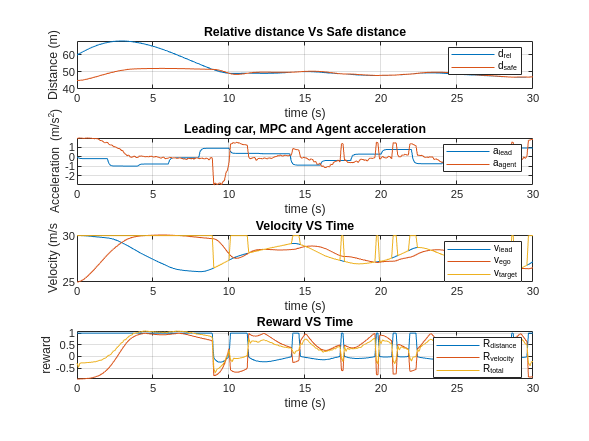

simOpts = rlSimulationOptions('MaxSteps',maxsteps,'StopOnError','on');

% get results
experiences = sim(env,agent,simOpts);
totalReward = sum(experiences.Reward);

% extract signals from simulation results
time = experiences.SimulationInfo.tout;
steps = size(time);
steps = steps(1);
d_safe = experiences.SimulationInfo.logsout.getElement('d_safe').Values.Data;
d_safe = reshape(d_safe, [steps,1]);
d_rel = experiences.SimulationInfo.logsout.getElement('d_rel').Values.Data;
d_rel = reshape(d_rel, [steps,1]);
action_a_ego = experiences.SimulationInfo.logsout.getElement('a_ego').Values.Data;
action_a_ego = reshape(action_a_ego, [steps,1]);
a_lead = experiences.SimulationInfo.logsout.getElement('a_lead').Values.Data;
a_lead = reshape(a_lead, [steps,1]);
v_lead = experiences.SimulationInfo.logsout.getElement('v_lead').Values.Data;
v_lead = reshape(v_lead, [steps,1]);
v_ego = experiences.SimulationInfo.logsout.getElement('v_ego').Values.Data;
v_ego = reshape(v_ego, [steps,1]);
v_target =  experiences.SimulationInfo.logsout.getElement('v_target').Values.Data;
v_target = reshape(v_target, [steps,1]);
d_reward = experiences.SimulationInfo.logsout.getElement('d_reward').Values.Data;
d_reward = reshape(d_reward, [steps,1]);
v_reward = experiences.SimulationInfo.logsout.getElement('v_reward').Values.Data;
v_reward = reshape(v_reward, [steps,1]);
all_reward = experiences.SimulationInfo.logsout.getElement('all_reward').Values.Data;
all_reward = reshape(all_reward, [steps,1]);

% plotting
figure(1);
subplot(4,1,1);
plot(time,d_rel, time, d_safe);
title('Relative distance Vs Safe distance');
legend('d_{rel}','d_{safe}');
xlabel('time (s)') ;
ylabel('Distance (m)') ;
grid on;

subplot(4,1,2);
plot(time,a_lead, time,action_a_ego);
title('Leading car, MPC and Agent acceleration');
legend('a_{lead}', 'a_{agent}');
xlabel('time (s)') ;
ylabel('Acceleration (m/s^{2})') ;
grid on;

subplot(4,1,3);
plot(time,v_lead, time, v_ego, time,v_target);
title('Velocity VS Time');
legend('v_{lead}','v_{ego}','v_{target}');
xlabel('time (s)') ;
ylabel('Velocity (m/s') ;
grid on;

subplot(4,1,4);
plot(time,d_reward, time, v_reward, time,all_reward);
title('Reward VS Time');
legend('R_{distance}', 'R_{velocity}', 'R_{total}');
xlabel('time (s)') ;
ylabel('reward') ;
grid on;

## Training progress info

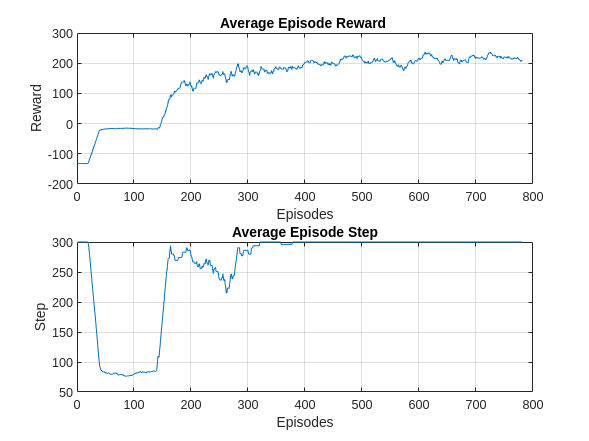

episodes = trainingStats.EpisodeIndex;
episode_reward = trainingStats.EpisodeReward;
episode_step = trainingStats.EpisodeSteps;
episode_avg_reward = trainingStats.AverageReward;
episode_avg_step = trainingStats.AverageSteps;

figure(2);
subplot(2,1,1)
plot(episodes,episode_avg_reward)
title('Average Episode Reward ')
xlabel('Episodes') 
ylabel('Reward') 
grid on

subplot(2,1,2)
plot(episodes,episode_avg_step)
title('Average Episode Step')
xlabel('Episodes') 
ylabel('Step') 
grid on

## Reset function

Randomized initial positions and velocities of ego and lead cars

function in = localResetFcn(in)
    % reset
    in = setVariable(in,'v_set', 25+randi(10,1,1));           % random value for user-set velocity
%     in = setVariable(in,'a_lead_seed', randi(10000));   % random value for a_lead generator seed
%     in = setVariable(in,'x0_lead', 60+randi(40,1,1));    % random value for lead car initial position
%     in = setVariable(in,'v0_lead', 20+randi(15,1,1));    % random value for lead car initial velocity
end
